# 'surface' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Create *povlab* object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Lights

pl.include_begin('lights');
    pl.light('location', [-10 -17 7],   'color', [2 2 2], 'shadowless', true);
    pl.light('location', [-10 10 30],   'color', [2 2 2], 'shadowless', true);
    pl.light('location', [100 200 300], 'color', [1 1 1], 'shadowless', true);
pl.include_end();

#### Environment

pl.include_begin('environment');
    pl.raw(['sky_sphere{ pigment{ gradient <0,0,1> '...
                      'color_map{ [0   color rgb<0.0,0.0, 0.0> ] '...
                                 '[0.4 color rgb<0.01, 0.01, 0.01>   ] '...
                                 '[0.9 color rgb<0.05, 0.05, 0.05>   ]  '...
                                 '[1.0 color rgb<0.1,0.1,0.1>     ]} '...
                      'scale 1  }}']);
pl.include_end();


#### Scene

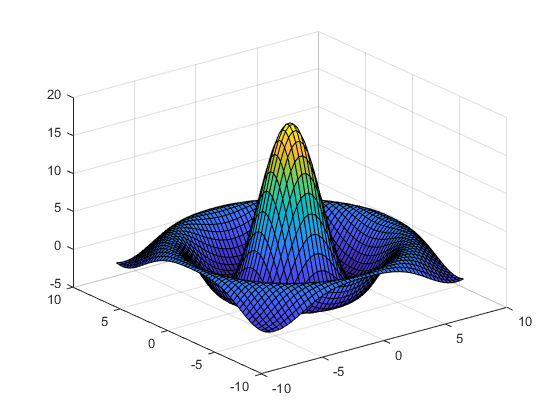

pl.scene_begin('scene_file', 'mesh.pov', 'image_file', 'mesh.png');
    pl.include("lights");
    pl.include("environment");    
    pl.include("textures");
    pl.include("glass");
    pl.include("metals");
    
    pl.global_settings("assumed_gamma 1");
    
%
% Surfaces
%
%     pl.camera('angle', 35, 'location', [-10 -10 6], 'look_at', [0 0 0], 'type', 'perspective');
%     size = 60;
%     % f = figure('Visible', 'off');
%     [X,Y,Z] = peaks(size);
%     s = surf(X,Y,Z);

%     pl.camera('angle', 35, 'location', [-12 -12 8], 'look_at', [0 0 0], 'type', 'perspective');
%     [X,Y] = meshgrid(-4:.2:4);
%     Z = Y.*sin(X) + X.*cos(Y);
%     s = surf(X,Y,Z,'FaceAlpha',0.5);

    pl.camera('angle', 35, 'location', [-25 -25 10], 'look_at', [0 0 0], 'type', 'perspective');
    t = linspace (-8, 8, 50);
    [x, y] = meshgrid (t, t);
    r = sqrt (x .^ 2 + y .^ 2) + eps;
    z = 18 * sin (r) ./ r;
    s = surf(x,y,z);


    % Ask a question (!)
%     pl.camera('angle', 35, 'location', [-15 -17 25], 'look_at', [2 2 4], 'type', 'perspective');
%     [X,Y] = meshgrid(1:0.3:10,1:0.3:20);
%     Z = sin(X)*3 + cos(Y)*3;
%     C = X.*Y;
%     s = surf(X,Y,Z,C);
   
    % -- Textures --
    % DMFWood6
    % NBglass            (Norm Bowler)
    % NBoldglass         (Norm Bowler)
    % NBwinebottle       (Norm Bowler)
    % NBbeerbottle       (Norm Bowler)
    % Ruby_Glass         (after Norm Bowler)
    % Dark_Green_Glass   (after Norm Bowler)
    % Yellow_Glass       (after Norm Bowler)
    % Orange_Glass       (after Norm Bowler)
    % Vicks_Bottle_Glass (after Norm Bowler)
    % Soft_Silver        (Dan Farmer)
    % New_Penny          (Dan Farmer)
    % Tinny_Brass        (Dan Farmer)
    % Gold_Nugget        (Dan Farmer)
    % Aluminum           (Dan Farmer)
    % Bright_Bronze      (Dan Farmer)
    % Lightening1        (Dan Farmer)
    % Lightening2        (Dan Farmer)
    % Brushed_Aluminum   (Dan Farmer)
    % Starfield          (Jeff Burton )
    % Shadow_Clouds      (Bill Pulver)

    % -- Glass --
    %     T_Glass1
    %     Simple clear glass.
    %     T_Glass2
    %     More like an acrylic plastic.
    %     T_Glass3
    %     An excellent lead crystal glass.
    %     T_Glass4
    %     T_Old_Glass
    %     T_Winebottle_Glass
    %     T_Beerbottle_Glass
    %     T_Ruby_Glass
    %     T_Green_Glass
    %     T_Dark_Green_Glass
    %     T_Yellow_Glass
    %     T_Orange_Glass
    %     Orange/amber glass.
    %     T_Vicksbottle_Glass
    

    pl.surface('surface', s, 'smooth', false, 'colormap', 'turbo', 'scale', [1, 1, 3/10], 'texture_odd', 'Silver1', 'texture_even', 'Vicks_Bottle_Glass');
%    pl.surface('surface', s, 'smooth', false, 'colormap', 'turbo', 'scale', [1, 1, 3/10], 'texture_odd', 'Aluminum', 'texture_even', 'T_Winebottle_Glass');
%    pl.surface('surface', s, 'smooth', false, 'colormap', 'turbo', 'scale', [1, 1, 3/10], 'texture_odd', 'Bright_Bronze', 'texture_even', 'Orange_Glass');
%    pl.surface('surface', s, 'smooth', false, 'colormap', 'turbo', 'scale', [1, 1, 3/10], 'texture_odd', 'Gold_Nugget', 'texture_even', 'T_Ruby_Glass');

pl.scene_end();

#### Rendering and display

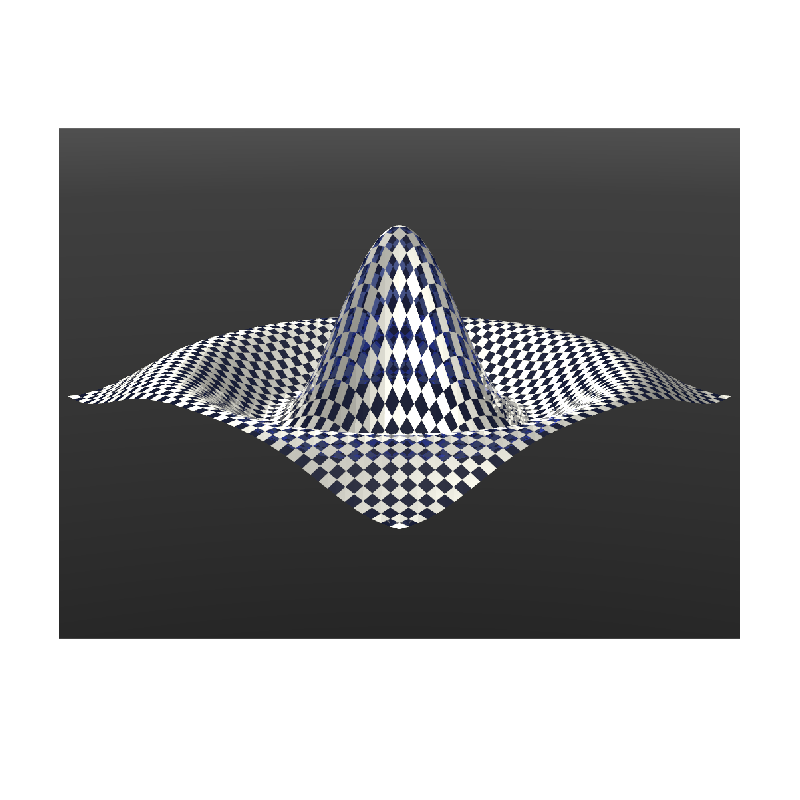

image = pl.render();
imshow(image);

#### Display elapsed time

toc % Elapsed time

Elapsed time is 5.815368 seconds.
